# Quad Copter VRFT

In `quad_copter_model.mlx` we have built and verified the quad-copter model. We can now attempt ot generate new controllers with VRFT. You will need to run this file now. 

## VRFT - The Inner Loop

The reference models we will be using are simply the complementary sensitivity  functions of the two loops. However since VRFT only works on discrete time systems we need to discretize all the systems:

InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);
OuterReferenceModel_dt = c2d(OuterReferenceModel, Ts);

InnerPlant_dt = c2d(PitchRateModel * Mixer, Ts);
OuterPlant_dt = c2d(integrator, Ts);

We have previously generated a set of input output data for the continous time plant. We will use this data as the input to the VRFT procedure.

The first step of the VRFT is to build the inner controller. This wil be a PID controller like the original.


$$C_i(z) = K_{Pi} + K_{Ii} \frac{1}{s} + K_{Di} \frac{s}{1 + sT_f} $$


We will use the same filter constant ($T_f = 0.01
$) that was used to build the initial controllers.

% We separate the proportional and derivative parts of the PID 
InnerControllerClass = [ 1, tf(1, [1 0]), tf([1 0], [Tf 1]) ].';
InnerControllerClass_dt = c2d(InnerControllerClass, Ts);

From here we can apply the VRFT method. We will reuse the PRBS input sequence we generated earlier as the VRFT input however we need to recalculate the outputs to account for the mixer matrix. Neglecting this will result in an error in the static gain of the controller.

Previously we just simulated the `PitchRateModel` because we were only considering the actual plant. The control loop however introduces the Mixer matrix that translates control outputs to plant inputs. Since it is not part of the controller we scale the plant input by the mixer value to compensate.

N = 1600;
vrft_time = [0:(N-1)] * Ts; 

in = idinput(N, 'prbs', [0 bw], [-signal_peak / Mixer, signal_peak / Mixer]);

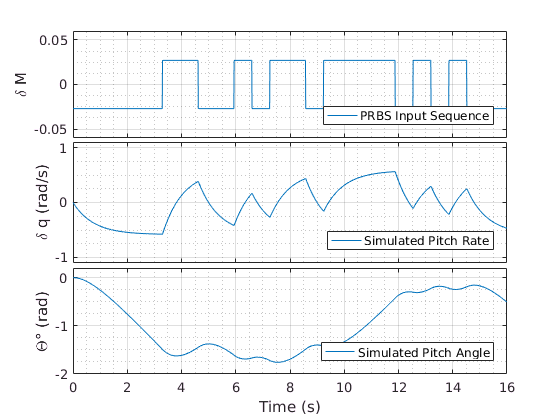

yi = lsim(InnerPlant_dt, in, vrft_time);
yo = lsim(OuterPlant_dt, yi, vrft_time);

figure();
    subplot 311;
        plot(time_vec, in);
        legend('PRBS Input Sequence', 'location', 'SouthEast');
        ylabel('\delta M'); grid minor; ylim([-0.06, 0.06]);
    subplot 312;
        plot(time_vec, yi); ylim([-1.1, 1.1]);
        legend('Simulated Pitch Rate', 'location', 'SouthEast');
        ylabel('\delta q (rad/s)'); grid minor;
    subplot 313;
        plot(time_vec, yo); ylim([-2. 0.2]);
        legend('Simulated Pitch Angle', 'location', 'SouthEast');
        ylabel('\Theta° (rad)'); xlabel('Time (s)'); grid minor;

condense_subplots('tight', true);


[OptimalInnerController, InnerControllerParams] = ...
    VRFT1_ry_theta(in, yi, InnerReferenceModel_dt, InnerControllerClass_dt, [], [], []);
OptimalInnerController.Variable = 'z^-1';

fprintf('The optimal PID parametters for the inner controller are: \n');

The optimal PID parametters for the inner controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', InnerControllerParams(1), R1.Kp);

Kp = +2.79843, Original: 0.3    


fprintf('Ki = %+7g, Original: %-7g\n', InnerControllerParams(2), R1.Ki);

Ki = -0.0438187, Original: 0.05   


fprintf('Kd = %+7g, Original: %-7g\n', InnerControllerParams(3), R1.Kd);

Kd = +0.0035306, Original: 0.3    


We can now compare the performance of the two controllers:

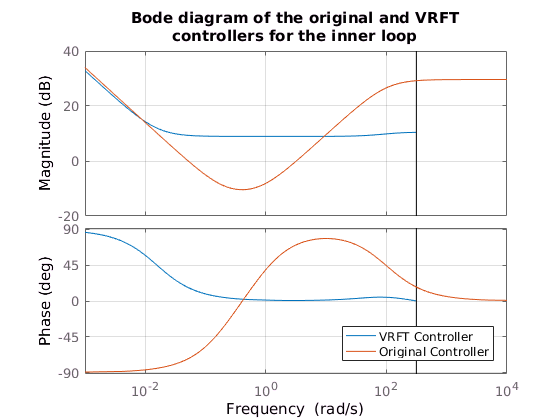

figure()
    bode(OptimalInnerController, Ri); grid on; 
    title({'Bode diagram of the original and VRFT' 'controllers for the inner loop'});
    legend('VRFT Controller', 'Original Controller', ...
        'location', 'SouthEast');

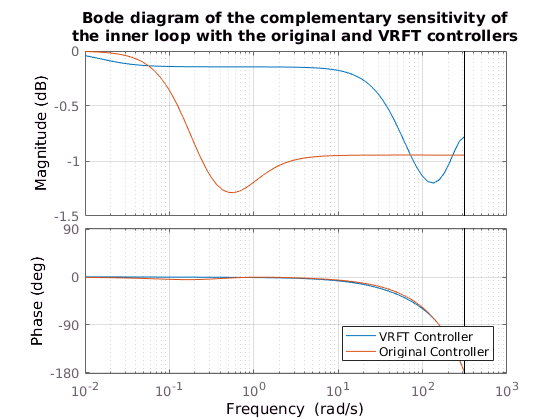


PitchRateModel_dt = c2d(tf(PitchRateModel), Ts);  
OptimalInnerLoop = loopsens(PitchRateModel_dt * Mixer, OptimalInnerController);     
    
figure()
    bode(OptimalInnerLoop.Ti, InnerReferenceModel_dt); grid on;
    title({'Bode diagram of the complementary sensitivity of', ...
        'the inner loop with the original and VRFT controllers'});
    legend('VRFT Controller', 'Original Controller', ...
        'location', 'SouthEast');

The match is excellent ! Even at high frequencies the phase and magnitude stay extremely close !

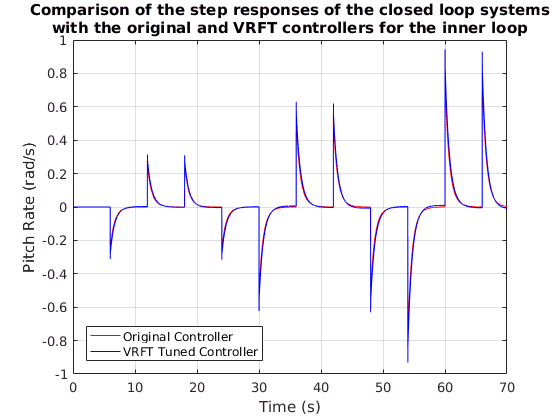

yi_vrft = lsim(OptimalInnerLoop.Ti, test_q_set_point, test_time_vec);

figure()
    plot(test_time_vec, test_output_q, 'r', test_time_vec, yi_vrft, 'b');
    title({'Comparison of the step responses of the closed loop systems' ...
        'with the original and VRFT controllers for the inner loop'});
    xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');
    legend('Original Controller', 'VRFT Tuned Controller', ...
        'location', 'southWest');

## VRFT - The Outer Loop

The outer controller is a PD. The controller class is thus: 

OuterControllerClass = [ 1, tf([1 0], [Tf 1]) ].';
OuterControllerClass_dt = c2d(OuterControllerClass, Ts);

We can now perform the VRFT on the outer loop. We already have the reference model but we still have to build the new vritual reference signal. This signal is simply: 


$$r_i(t) = e_i(t) + y_i(t) = C_i^{-1}(z) \ u(t) + y_i(t) 
$$


Where $C_i(z)$ is the inner controller. The reasoning behind this is detailed in my [thesis log](http://thesis.comkieffer.com/pages/cascade-vrft.html).

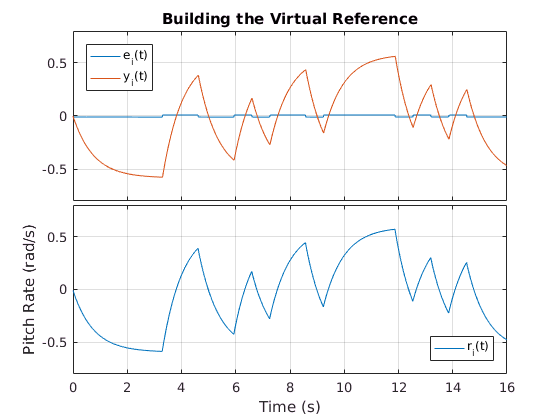

ei = lsim(OptimalInnerController^-1, in, vrft_time); % Inner error signal.
ri = ei + yi;                                        % Virtual Reference signal.

% Verify the results
figure;
    subplot 211;
        plot(vrft_time, ei, vrft_time, yi);
        legend('e_i(t)', 'y_i(t)', 'location', 'northWest');
        title('Building the Virtual Reference'); ylim([-.8, .8]);
    subplot 212;
        plot(vrft_time, ri);
        legend('r_i(t)', 'location', 'southEast'); ylim([-.8, .8]);
        xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');
condense_subplots('tight', true);        

Now that we know that the generated data is good we can move on to the actual VRFT.

[OptimalOuterController, OuterControllerParams] = ...
    VRFT1_ry_theta(ri, yo, OuterReferenceModel_dt, OuterControllerClass_dt, [], [], []);
OptimalOuterController.Variable = 'z^-1';

fprintf('The optimal PID parametters for the outer controller are: \n');

The optimal PID parametters for the outer controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', OuterControllerParams(1), R1.Kp);

Kp = +1.45143, Original: 0.3    


fprintf('Kd = %+7g, Original: %-7g\n', OuterControllerParams(2), R1.Kd);

Kd = +0.0145847, Original: 0.3    


Again, we compare the perfomance of the original controller and the PID controller: 

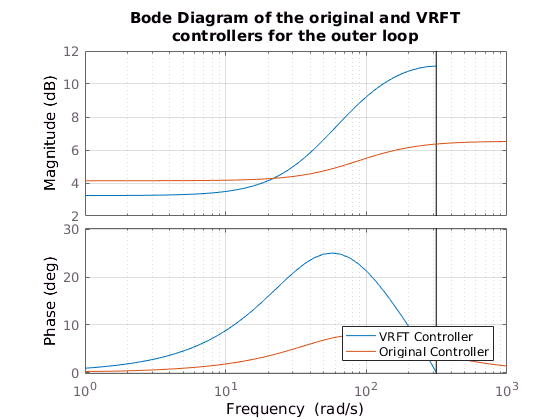

figure()
    bode(OptimalOuterController, Ro);
    grid on; 
    title({'Bode Diagram of the original and VRFT' 'controllers for the outer loop'});
    legend('VRFT Controller', 'Original Controller', ...
        'location', 'SouthEast');

And the closed loop responses using the series of  steps data:

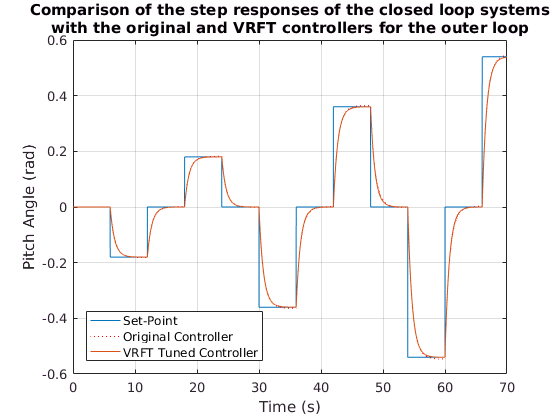

OptimalOuterLoop = loopsens(OuterPlant_dt * OptimalInnerLoop.Ti, OptimalOuterController); 
yo_vrft = lsim(OptimalOuterLoop.Ti, test_theta_set_point, test_time_vec);

figure()
    plot(test_time_vec, test_theta_set_point, ...
         test_time_vec, test_theta, 'r:', test_time_vec, yo_vrft);
    title({'Comparison of the step responses of the closed loop systems' ...
        'with the original and VRFT controllers for the outer loop'});
    xlabel('Time (s)'); ylabel('Pitch Angle (rad)');
    legend('Set-Point', 'Original Controller', 'VRFT Tuned Controller', ...
        'location', 'southWest');